# **Programming a Simple Game in MATLAB**

**or**

## **A Brief Guide to the Fundamentals of Object Oriented Programming (OOP)**

**or**

### **A Whistle Stop Tour of Software Development and Some MATLAB Features We Didn't Have Time to Cover**

**or**

### **How I Learned to Stop Worrying About Crippling Perfectionism and Embrace the Chaos of Using Multiple Titles at Once***

#### **The views expressed in this document are those of the individual and are not endorsed by Heriot-Watt University. This is not medical advice and I am not a mental health professional.*

- Something a bit different - essentially a computer science lecture.

- The goal is to bring concepts and tools to your attention for future reference.

- No expectation to understand and process all this information.

- **Please ask questions!**

### **The Inspiration Behind the Elective**

My "entry" for the Halloween coding contest when I was taking this course in 2019; 

but first, **Full Disclosure:**

*<Insert Timeline Here>*

How it started:

[Original code without OOP](matlab:open('./examples\snakeLab\dev2019\Snake_Test_Optimise_Robarts.m'))

Snake_Test_Optimise_Robarts;
return

### Five Years Later

[OOP implementation for this elective](matlab:open('./examples\snakeLab\dev2024\snakeAppSetup.m'))

Overly complex code due to an ever increasing obsession with generality...

snakeAppSetup;
return

### **Template for Real Time App Implementation**

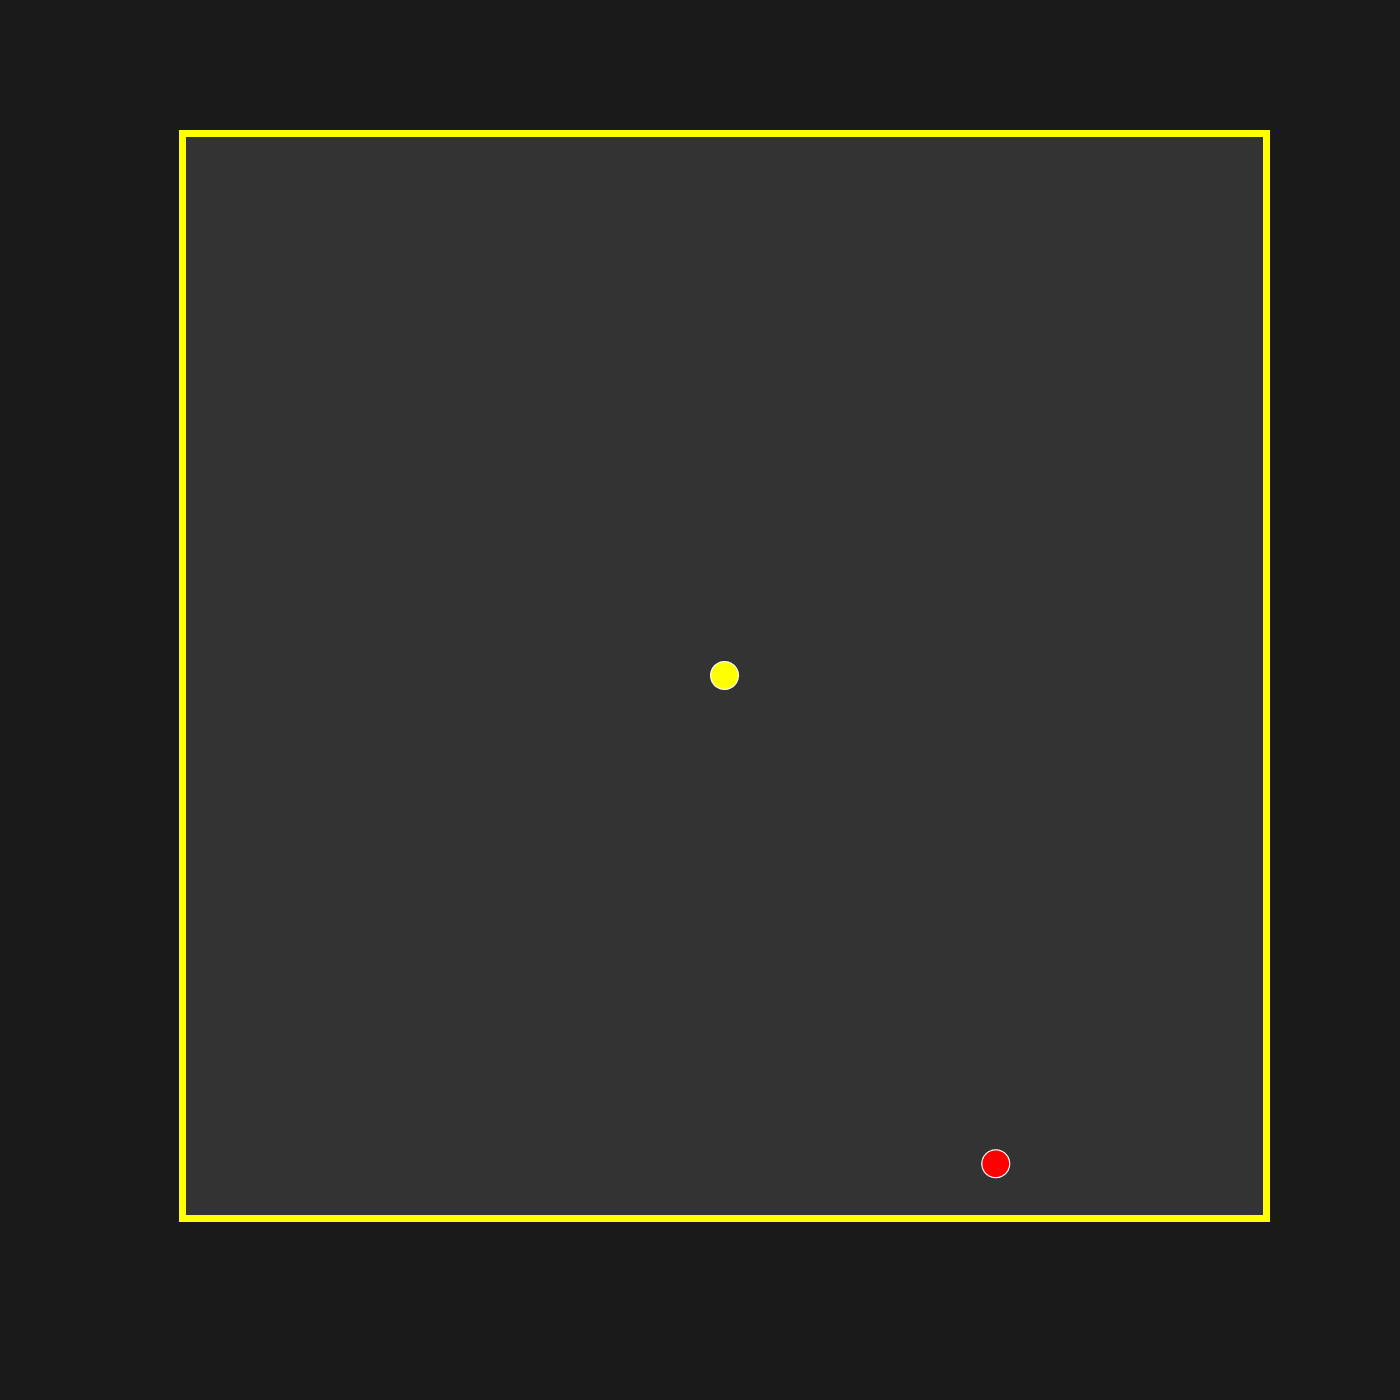

%% Blank Canvas
close all; clear all; %#ok<CLALL>

%% Create New Instance of the RealTimeApp Class
newApp = RealTimeApp;
newApp.TargetFPS = 60;
newApp.GridStep = 0.5;

%% Initialise local variables and objects which will be referenced in app functions
staticVar = 'foo';	% static variables can be used to pass fixed values to the functions

function myObj = createObj(name,colour,relativePosition)
arguments
	name
	colour = 'w';
	relativePosition = [0,0]; % assign default values to make arguments optional
end
	myObj = MobileEntity;
	myObj.Name = name;
	myObj.addprop('customProperty'); % Add properties to store anything you like with the object
	myObj.Position = relativePosition;
	myObj.PlotOptions = {'o','MarkerSize',12,'MarkerEdgeColor','w','MarkerFaceColor',colour};
end

userObj = createObj("User",'y');	% handle objects store data across workspaces	
autoObj = createObj("Auto",'r',[0.5,-0.9]);
userObj.Speed = 0.05;
autoObj.Speed = 0.1;
autoObj.AutoMove = 1;

%% Add custom objects to the app
objList = [userObj,autoObj];
newApp.Entities = objList;

%% Set the core app functions
function keyInput(press,varargin)
obj = varargin{2};
obj.WillStep = 1;
	switch press.Key
		case {'uparrow','w'}
			obj.Direction = [0,1];
		case {'leftarrow','a'}
			obj.Direction = [-1,0];
		case {'downarrow','s'}
			obj.Direction = [0,-1];
		case {'rightarrow','d'}
			obj.Direction = [1,0];
		otherwise
			disp([press.Key, ' ', varargin{1}]);
			obj.WillStep = 0;
	end
end

function mainLoop(app,objList)
	if ~app.BeingDeleted
		frame = app.FrameCount;
		updateLocalObj(objList(2),frame);
	end
end

newApp.KeyPressFcn = @(press) keyInput(press,staticVar,userObj);
newApp.MainLoopFcn = @() mainLoop(newApp,objList);

%% Initialise and start the app
newApp.initialise;
newApp.start;


%% Local functions
function updateLocalObj(obj,val)
	obj.customProperty = val;
end
return